## Dados do sensor

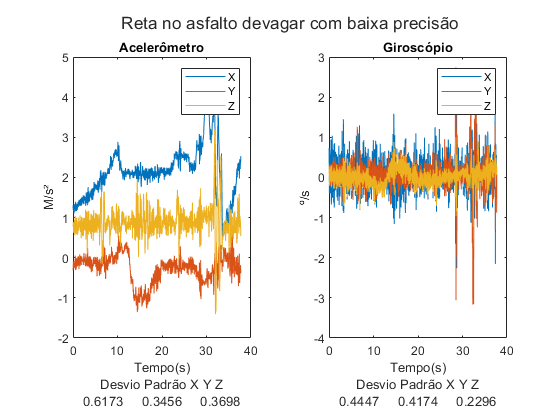

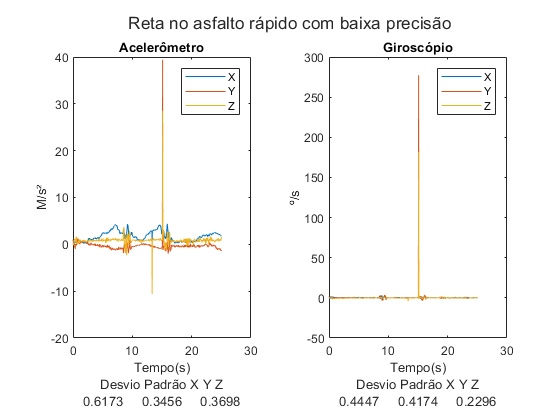

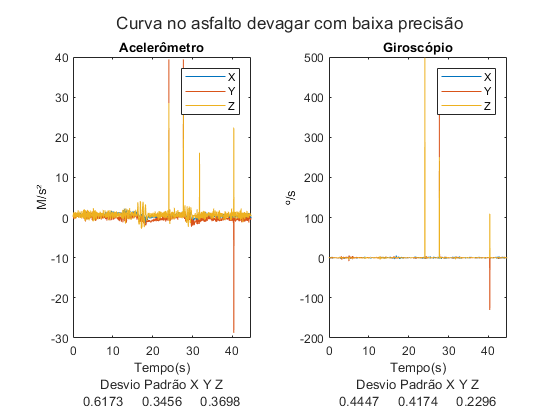

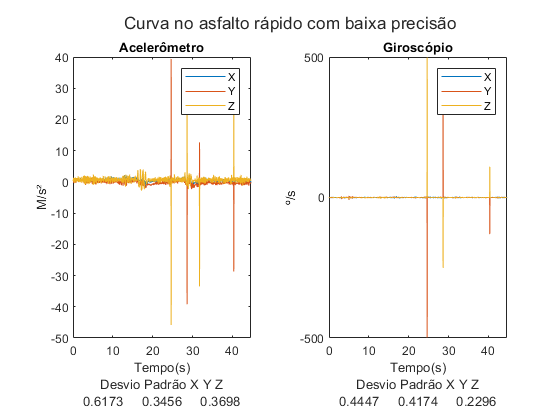

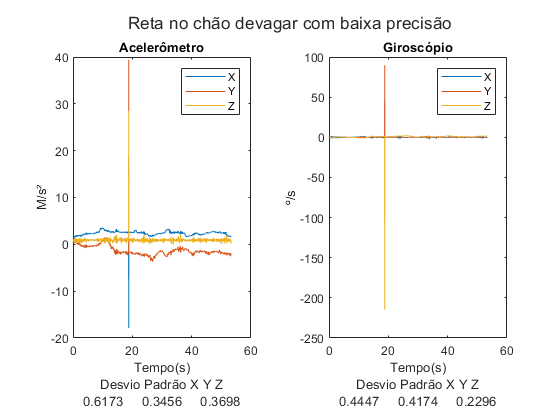

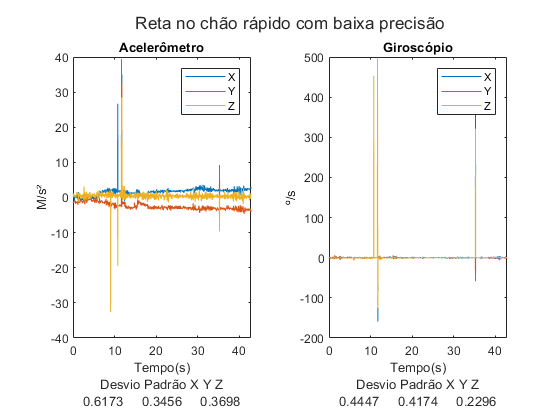

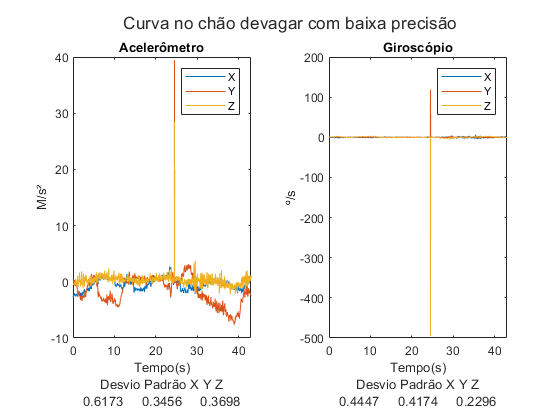

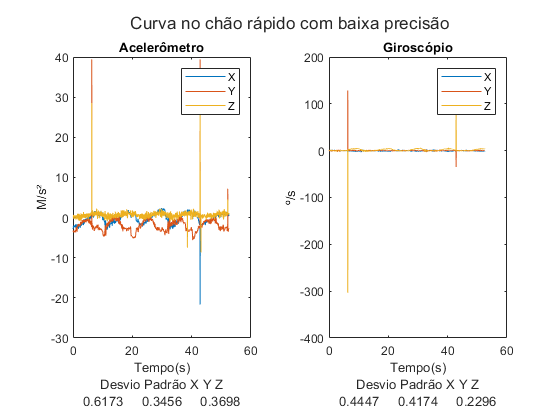

load('Leitura.mat')
%graficos
for i=1:length(medicoes)
    %inicializando
    Ax=medicoes(i).valores.Ax;
    Ay=medicoes(i).valores.Ay;
    Az=medicoes(i).valores.Az;
    Gx=medicoes(i).valores.Gx;
    Gy=medicoes(i).valores.Gy;
    Gz=medicoes(i).valores.Gz;
    Tempo=medicoes(i).valores.Ms/1000;
    
    figure;
    t=tiledlayout(1,2);
    ax1=nexttile;
    plot(ax1,Tempo,Ax,Tempo,Ay,Tempo,Az);
    ax2=nexttile;
    plot(ax2,Tempo,Gx,Tempo,Gy,Tempo,Gz);
    
    titulo= "";
    switch medicoes(i).R
        case 1
            titulo = titulo + "Reta no asfalto devagar ";
        case 2
            titulo = titulo + "Reta no asfalto rápido ";
        case 3
            titulo = titulo + "Curva no asfalto devagar ";
        case 4
            titulo = titulo + "Curva no asfalto rápido ";
        case 5
            titulo = titulo + "Reta no chão devagar ";
        case 6
            titulo = titulo + "Reta no chão rápido ";
        case 7
            titulo = titulo + "Curva no chão devagar ";
        case 8
            titulo = titulo + "Curva no chão rápido ";
    end
    switch medicoes(i).A
        case 1
            titulo =titulo + "com baixa precisão";
        case 4
            titulo =titulo + "com alta precisão";
    end
    %case rotas
    title(t,titulo);
    title(ax1,"Acelerômetro");
    title(ax2,"Giroscópio");
    legend(ax1,{'X','Y','Z'});
    legend(ax2,{'X','Y','Z'});
    xlabel(ax1,["Tempo(s)","Desvio Padrão X Y Z",num2str(std(medicoes(1).valores{:,{'Ax','Ay','Az'}}),4)]);
    ylabel(ax1,'M/s²');
    xlabel(ax2,['Tempo(s)',"Desvio Padrão X Y Z",num2str(std(medicoes(1).valores{:,{'Gx','Gy','Gz'}}),4)]);
    ylabel(ax2,'º/s');
end

clearvars -except medicoes

## Integração Trapezoidal Simples

%concentrar nos lineares
for i=1:length(medicoes)
    %inicializando
    Ax=medicoes(i).valores.Ax;
    Ay=medicoes(i).valores.Ay;
    Az=medicoes(i).valores.Az;
    Gx=medicoes(i).valores.Gx;
    Gy=medicoes(i).valores.Gy;
    Gz=medicoes(i).valores.Gz;
    Tempo=medicoes(i).valores.Ms/1000;
    %integracoes 
    Vx=cumtrapz(Tempo,Ax);
    Vy=cumtrapz(Tempo,Ay);
    Vz=cumtrapz(Tempo,Az);
    Wx=Gx;
    Wy=Gy;
    Wz=Gz;   
    
    Sx=cumtrapz(Tempo,Vx);
    Sy=cumtrapz(Tempo,Vy);
    Sz=cumtrapz(Tempo,Vz);
    Degx=cumtrapz(Tempo,Wx);
    Degy=cumtrapz(Tempo,Wy);
    Degz=cumtrapz(Tempo,Wz);
    
    figure;
    t=tiledlayout(2,2);
    ax1=nexttile;
    plot(ax1,Tempo,Vx,Tempo,Vy,Tempo,Vz);
    ax2=nexttile;
    plot(ax2,Tempo,Wx,Tempo,Wy,Tempo,Wz);
    ax3=nexttile;
    plot(ax3,Tempo,Sx,Tempo,Sy,Tempo,Sz);
    ax4=nexttile;
    plot(ax4,Tempo,Degx,Tempo,Degy,Tempo,Degz);
    
    titulo= "";
    switch medicoes(i).R
        case 1
            titulo = titulo + "Reta no asfalto devagar ";
        case 2
            titulo = titulo + "Reta no asfalto rápido ";
        case 3
            titulo = titulo + "Curva no asfalto devagar ";
        case 4
            titulo = titulo + "Curva no asfalto rápido ";
        case 5
            titulo = titulo + "Reta no chão devagar ";
        case 6
            titulo = titulo + "Reta no chão rápido ";
        case 7
            titulo = titulo + "Curva no chão devagar ";
        case 8
            titulo = titulo + "Curva no chão rápido ";
    end
    switch medicoes(i).A
        case 1
            titulo =titulo + "com baixa precisão";
        case 4
            titulo =titulo + "com alta precisão";
    end
    %case rotas
    title(t,titulo);
    title(ax1,"Vel. Linear");
    title(ax2,"Vel. Angular");
    title(ax3,"Desl. Linear");
    title(ax4,"Desl. Angular");
    legend(ax1,{'X','Y','Z'});
    legend(ax2,{'X','Y','Z'});
    legend(ax3,{'X','Y','Z'});
    legend(ax4,{'X','Y','Z'});
    xlabel(ax1,'Tempo(s)');
    ylabel(ax1,'M/s');
    xlabel(ax2,'Tempo(s)');
    ylabel(ax2,'º/s');
    xlabel(ax3,'Tempo(s)');
    ylabel(ax3,'Metros');
    xlabel(ax4,'Tempo(s)');
    ylabel(ax4,'º');
end
clearvars -except medicoes

## Integração por Triangulos

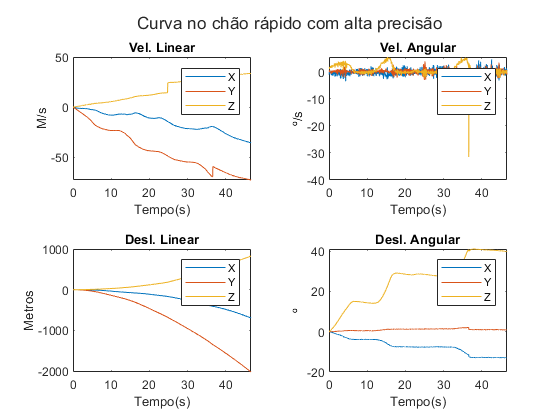

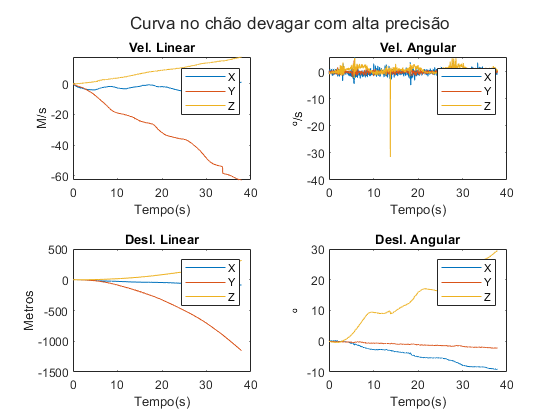

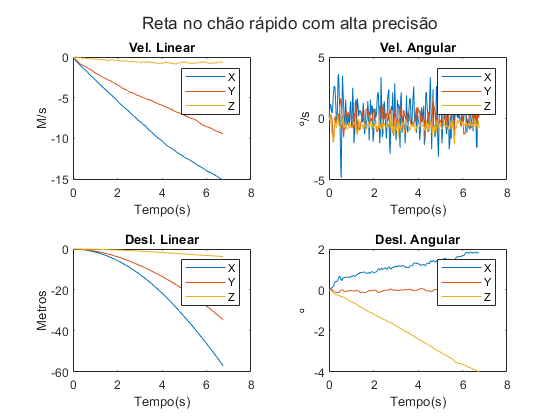

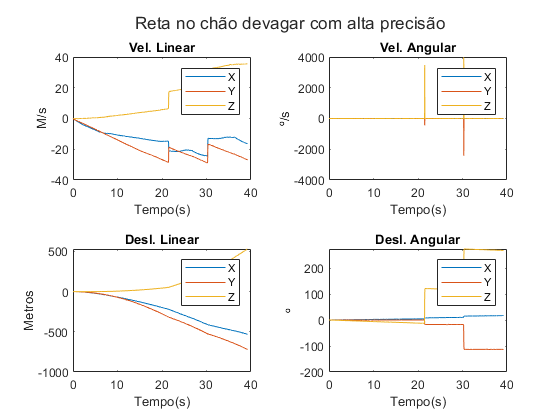

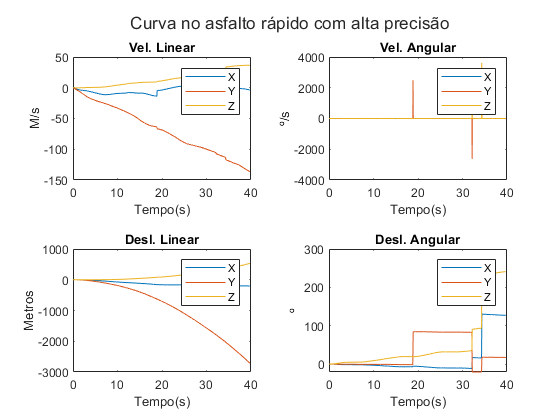

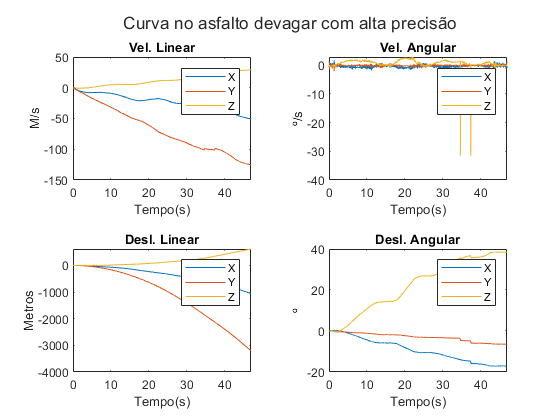

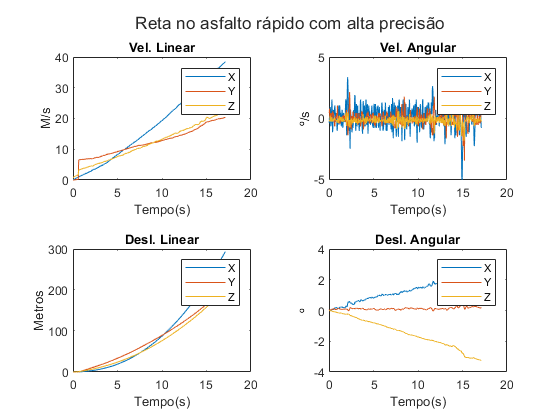

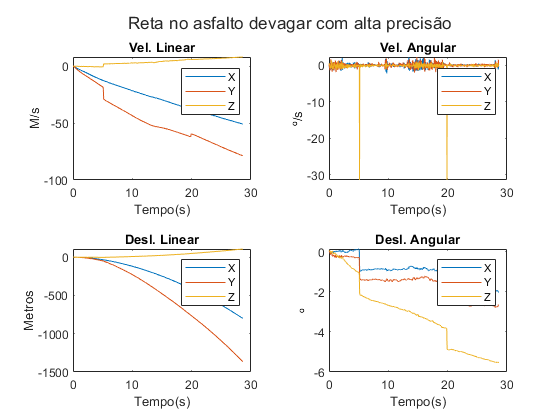

%ATtriang(x,y,n) para qualquer ponto n
for i=1:length(medicoes)
    %inicializando
    Ax=medicoes(i).valores.Ax;
    Ay=medicoes(i).valores.Ay;
    Az=medicoes(i).valores.Az;
    Gx=medicoes(i).valores.Gx;
    Gy=medicoes(i).valores.Gy;
    Gz=medicoes(i).valores.Gz;
    Tempo=medicoes(i).valores.Ms/1000;%integracoes 
    Vx=IntTriang(Tempo,Ax);
    Vy=IntTriang(Tempo,Ay);
    Vz=IntTriang(Tempo,Az);
    Wx=Gx;
    Wy=Gy;
    Wz=Gz;   
    
    Sx=IntTriang(Tempo,Vx);
    Sy=IntTriang(Tempo,Vy);
    Sz=IntTriang(Tempo,Vz);
    Degx=IntTriang(Tempo,Wx);
    Degy=IntTriang(Tempo,Wy);
    Degz=IntTriang(Tempo,Wz);
    
    figure;
    t=tiledlayout(2,2);
    ax1=nexttile;
    plot(ax1,Tempo,Vx,Tempo,Vy,Tempo,Vz);
    ax2=nexttile;
    plot(ax2,Tempo,Wx,Tempo,Wy,Tempo,Wz);
    ax3=nexttile;
    plot(ax3,Tempo,Sx,Tempo,Sy,Tempo,Sz);
    ax4=nexttile;
    plot(ax4,Tempo,Degx,Tempo,Degy,Tempo,Degz);
    
    titulo= "";
    switch medicoes(i).R
        case 1
            titulo = titulo + "Reta no asfalto devagar ";
        case 2
            titulo = titulo + "Reta no asfalto rápido ";
        case 3
            titulo = titulo + "Curva no asfalto devagar ";
        case 4
            titulo = titulo + "Curva no asfalto rápido ";
        case 5
            titulo = titulo + "Reta no chão devagar ";
        case 6
            titulo = titulo + "Reta no chão rápido ";
        case 7
            titulo = titulo + "Curva no chão devagar ";
        case 8
            titulo = titulo + "Curva no chão rápido ";
    end
    switch medicoes(i).A
        case 1
            titulo =titulo + "com baixa precisão";
        case 4
            titulo =titulo + "com alta precisão";
    end
    %case rotas
    title(t,titulo);
    title(ax1,"Vel. Linear");
    title(ax2,"Vel. Angular");
    title(ax3,"Desl. Linear");
    title(ax4,"Desl. Angular");
    legend(ax1,{'X','Y','Z'});
    legend(ax2,{'X','Y','Z'});
    legend(ax3,{'X','Y','Z'});
    legend(ax4,{'X','Y','Z'});
    xlabel(ax1,'Tempo(s)');
    ylabel(ax1,'M/s');
    xlabel(ax2,'Tempo(s)');
    ylabel(ax2,'º/s');
    xlabel(ax3,'Tempo(s)');
    ylabel(ax3,'Metros');
    xlabel(ax4,'Tempo(s)');
    ylabel(ax4,'º');
end

clearvars -except medicoes

## Filtro de Kalman

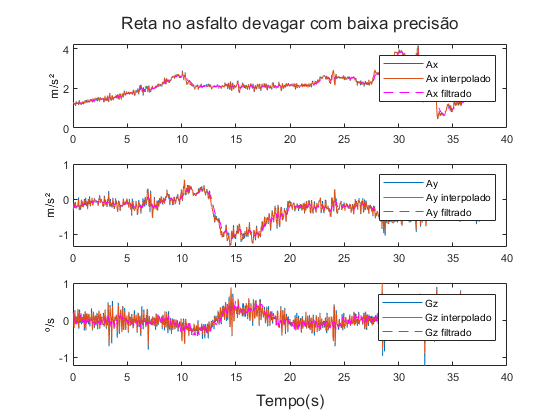

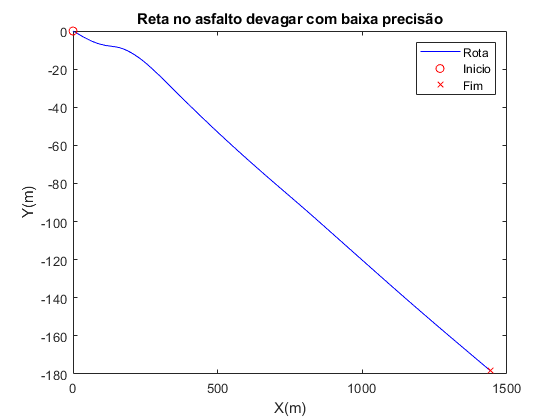

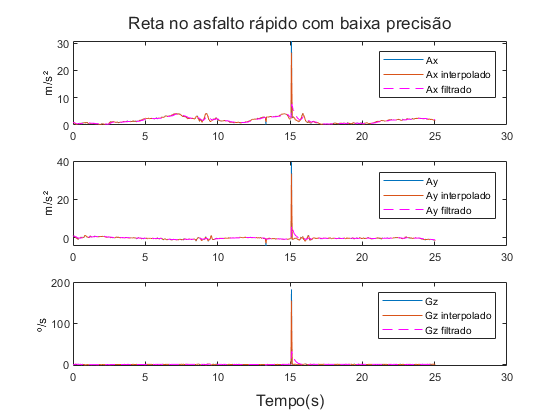

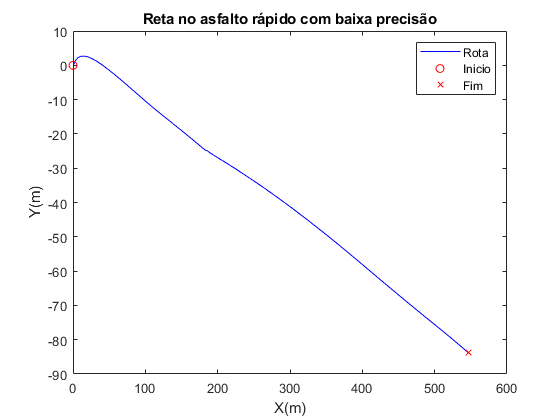

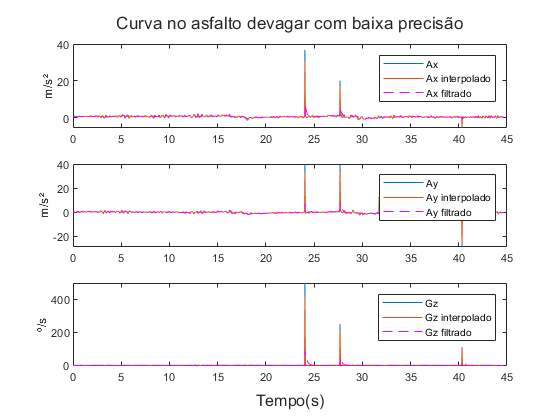

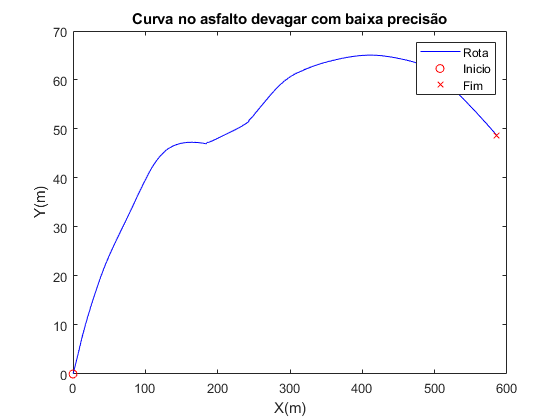

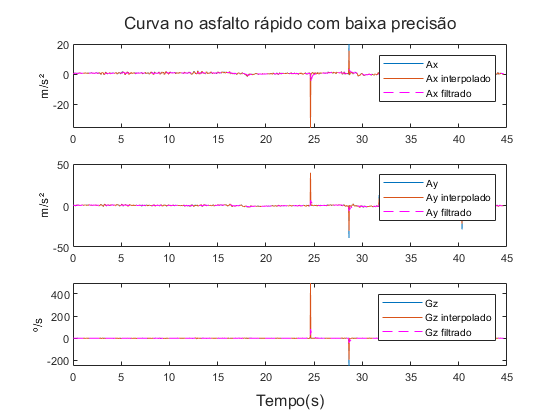

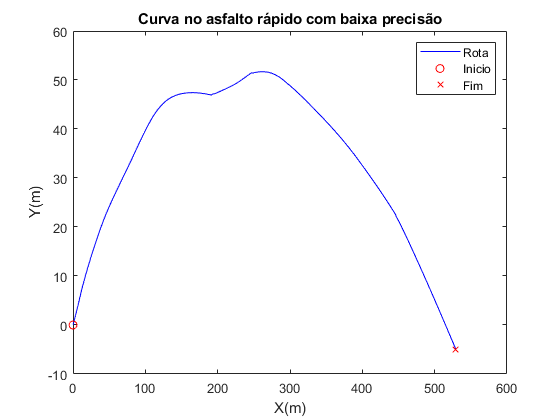

FiltroKaiman